# ScatterFit

**Overview**

The `ScatterFit` chart manages bivariate scattered data together with a best-fit trend line (regression line). The chart data comprises numeric vectors `XData` and `YData`. The `YData` is scattered against the `XData` and the best-fit line is computed using the `fitlm` function to perform linear regression.

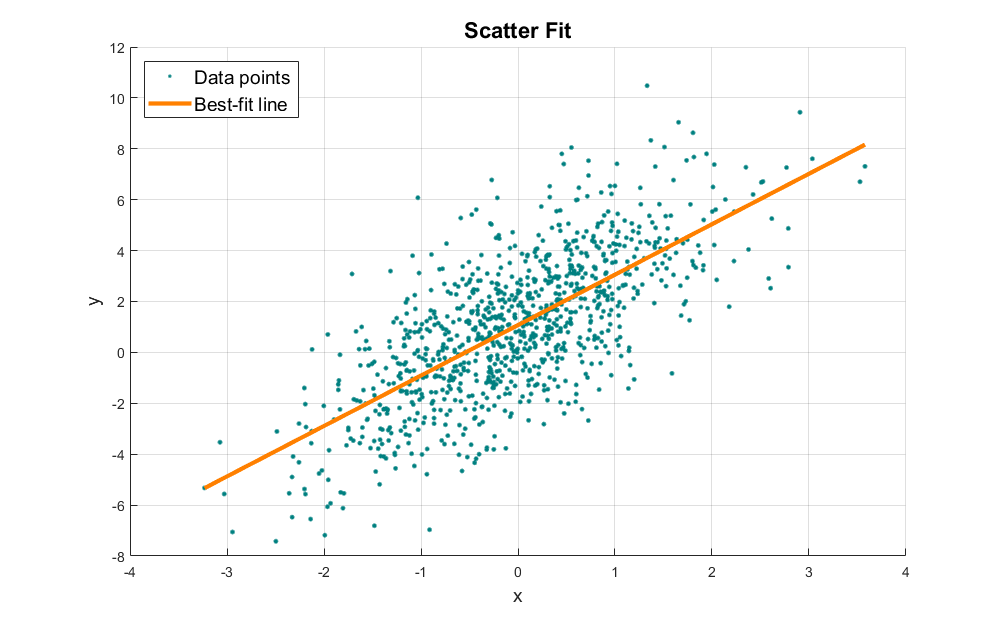

**Resources**

[Open](matlab: edit(fullfile(galleryRoot, '+Examples', 'ScatterFit.mlx'))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(galleryRoot, '+Charts', 'ScatterFit'))) the source code for the `ScatterFit` chart.

Documentation for [fitlm](matlab: web(fullfile(matlabroot, 'help', 'stats', 'fitlm.html'), '-helpbrowser')).

Copyright 2018 The MathWorks, Inc.

## Import the chart.

import Charts.ScatterFit

## Create sample x and y data for the chart.

rng default
x = randn( 1000, 1 );
y = 2 * x + 1 + 2 * randn( size( x ) );

## Create a figure for the chart.

f = galleryFigure( 'Name', 'ScatterFit Example' );

## Create the chart.

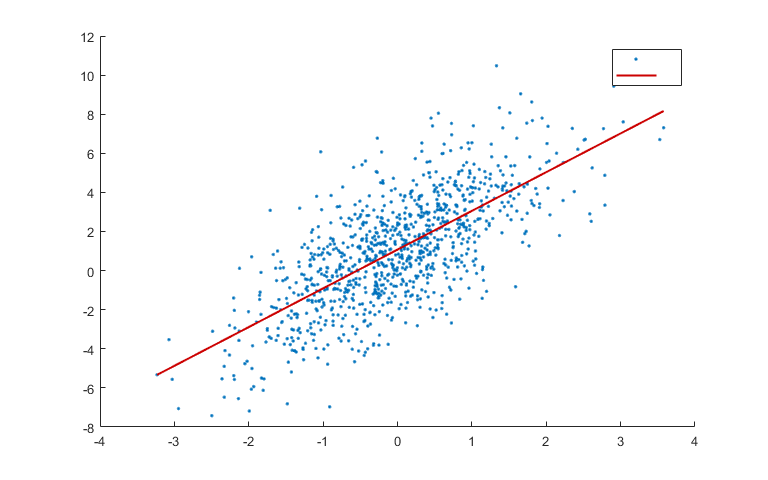

SF = ScatterFit( 'Parent', f, ...
                 'XData', x, ...
                 'YData', y );

## Annotate the chart.

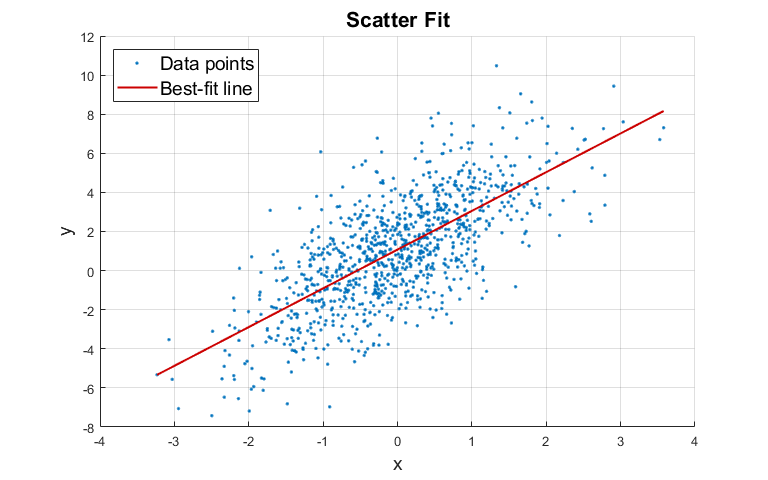

set( SF.XLabel, 'String', 'x', 'FontSize', 14 )
set( SF.YLabel, 'String', 'y', 'FontSize', 14 )
set( SF.Title, 'String', 'Scatter Fit', 'FontSize', 16 )
SF.Grid = 'on';
SF.LegendText = {'Data points', 'Best-fit line'};
SF.LegendFontSize = 14;
SF.LegendLocation = 'northwest';

## Customize the chart by adjusting its graphics properties.

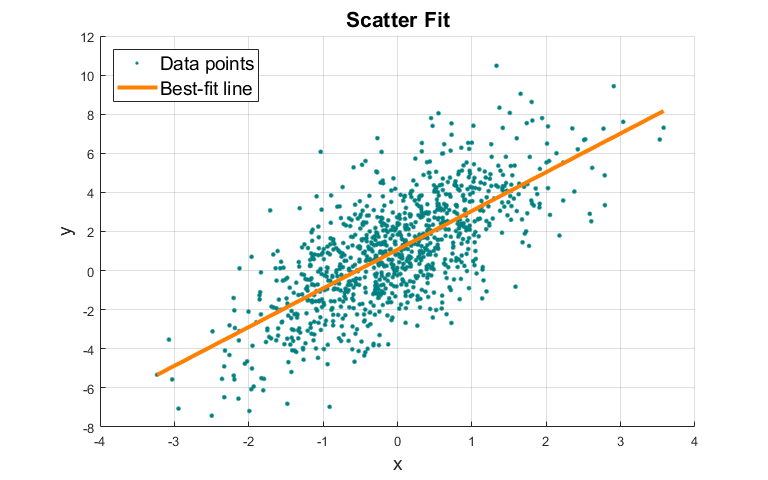

SF.LineColor = [1, 0.5, 0];
SF.LineWidth = 3;
SF.CData = [0, 0.5, 0.5];
SF.SizeData = 100;

## Update the chart data.

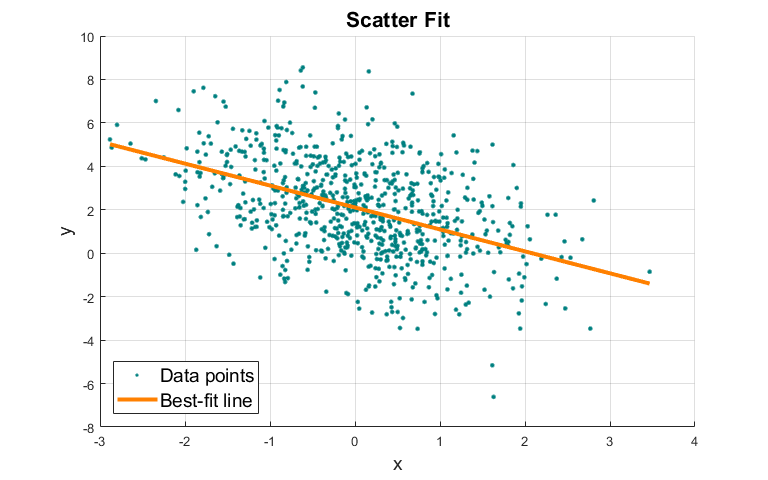

SF.XData = randn( 750, 1 );
SF.YData = (-1) * SF.XData + 2 + 2 * randn( size( SF.XData ) );
SF.LegendLocation = 'southwest';